# Project 3 (CNN classifier)

Imola Fodor, Romina Doz

## Import Datastores

trainDatasetPath = fullfile('Images','train');
testDatasetPath = fullfile('Images','test');

imdsInit = imageDatastore(trainDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore(testDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

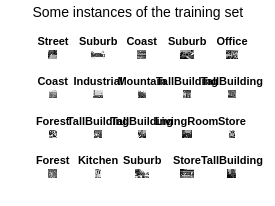

% show some instances
figure;
perm = randperm(length(imdsInit.Labels),20);
for ii = 1:20
    subplot(4,5,ii);
    imshow(imdsInit.Files{perm(ii)}); 
    title(imdsInit.Labels(perm(ii)));
end
sgtitle('Some instances of the training set')

### Split Dataset and Labels

quotaForEachLabel=0.85;
[imdsTrain,imdsValidation] = splitEachLabel(imdsInit,quotaForEachLabel,'randomize');

YTrain = imdsTrain.Labels;
YValidation = imdsValidation.Labels;
YTest = imdsTest.Labels;

## 1. Baseline Model

### Data preparation

imdsTrain.ReadFcn = @(x)imresize(imread(x),[64, 64]);
imdsValidation.ReadFcn = @(x)imresize(imread(x),[64, 64]);
imdsTest.ReadFcn = @(x)imresize(imread(x),[64, 64]);

### Network design , hyperparameters and training

Design a baseline network, following the given layout.

Train it and gradually improve the value of the learning rate.

layers = [
    imageInputLayer([64 64 1],'Name','input') 
    convolution2dLayer(3,8,'WeightsInitializer','narrow-normal', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(3,16,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_2')
    reluLayer('Name','relu_2')
    
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(3,32,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_3')
    reluLayer('Name','relu_3')
    
    fullyConnectedLayer(15,'WeightsInitializer','narrow-normal','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

    lgraph = layerGraph(layers);
    %analyzeNetwork(lgraph)

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ... 
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'ValidationPatience',10,... 
    'Verbose',false, ...
    'MiniBatchSize',32, ...
    'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 32
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 10
              ValidationPatience: 10
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: 

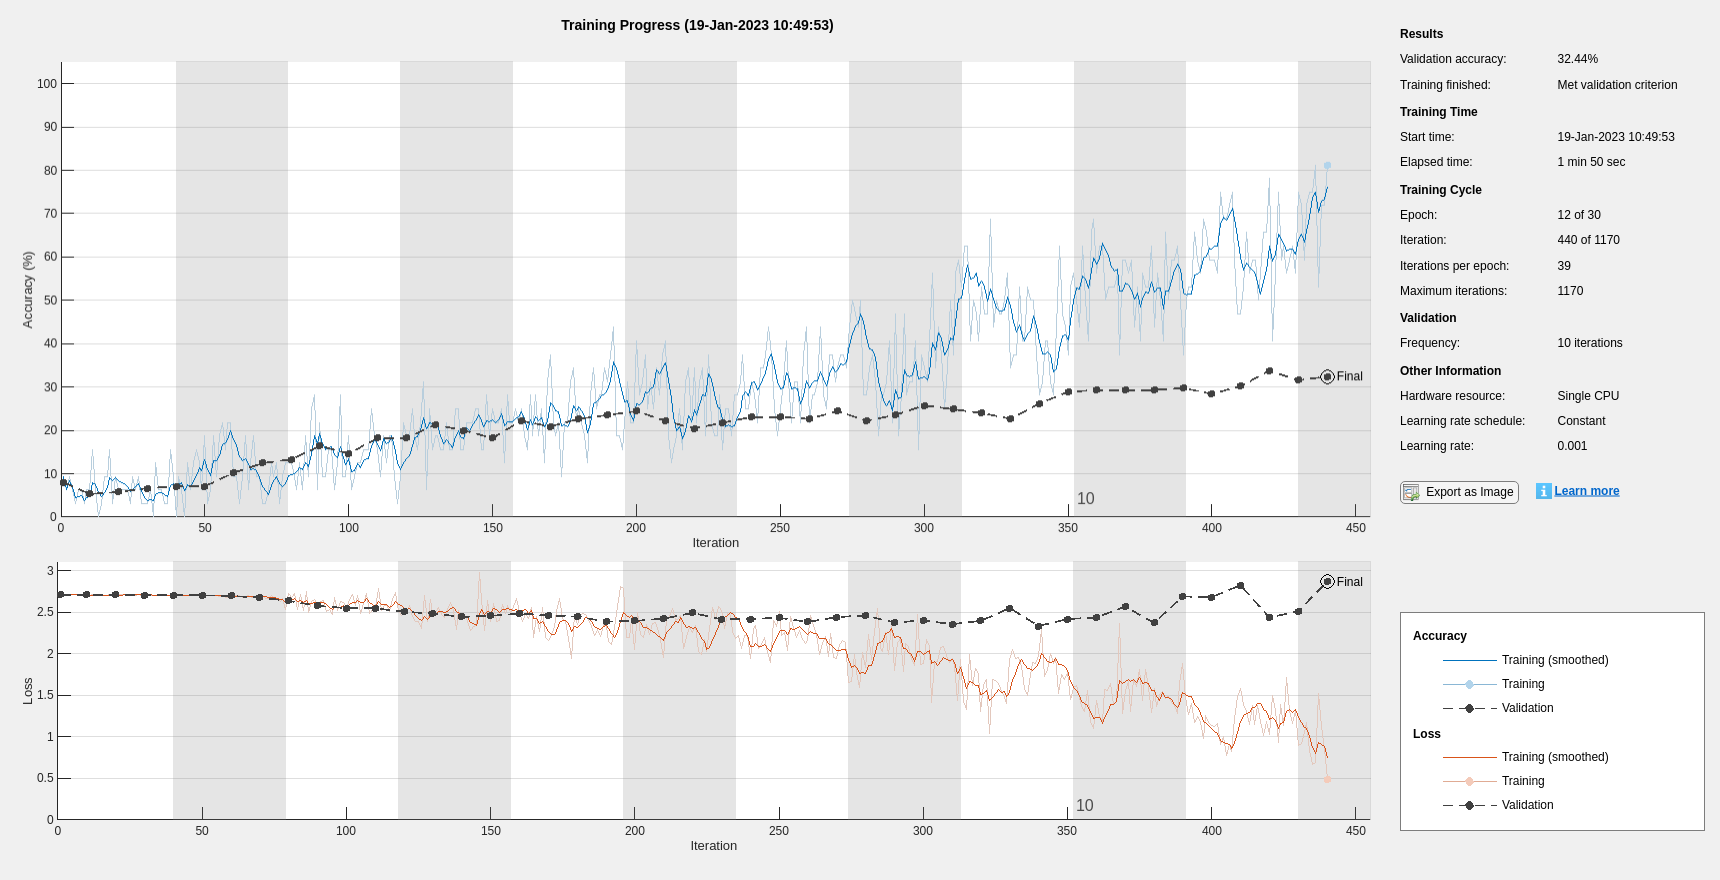

net_0 = trainNetwork(imdsTrain,layers,options);

### Apply the network to the test set

YPredicted = classify(net_0,imdsTest);

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.3022

### Confusion matrix

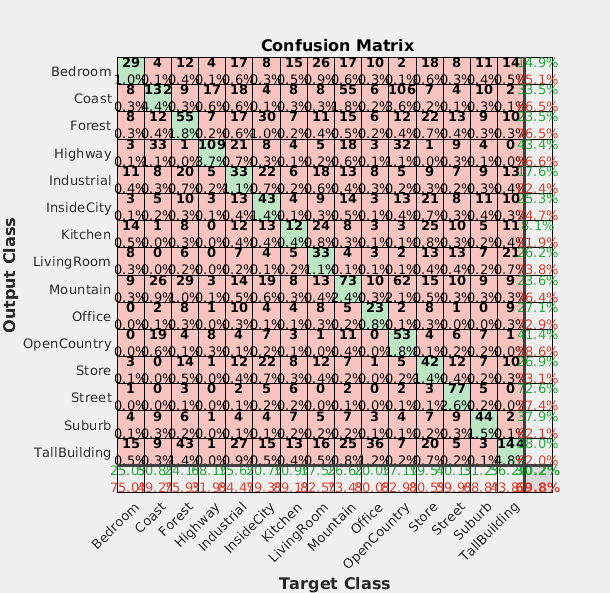

figure
plotconfusion(YTest,YPredicted)

## 2. Improve the Baseline Model

### Data augmentation

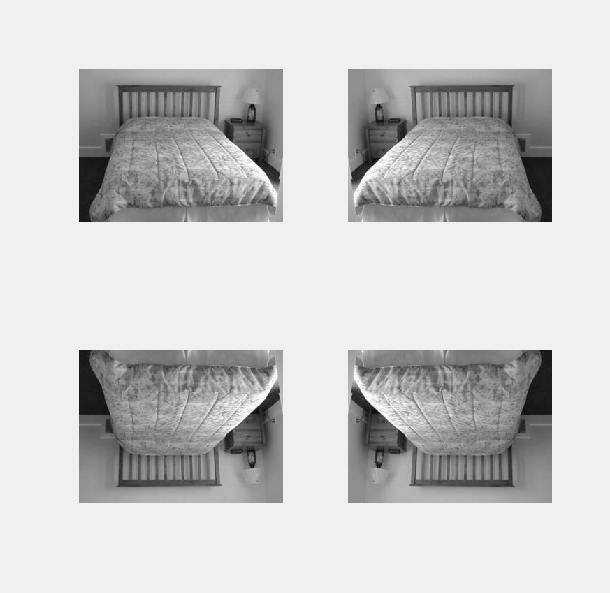

%Now let's try data augmentation by considering the horizontal mirroring of
%the images. The possibilities for mirroring are the following:
iimage=100;
I = imdsInit.readimage(iimage);
I2 = flip(I ,2);           %# horizontal flip
I3 = flip(I ,1);           %# vertical flip
I4 = flip(I3,2);    %# horizontal+vertical flip
subplot(2,2,1), imshow(I)
subplot(2,2,2), imshow(I2)
subplot(2,2,3), imshow(I3)
subplot(2,2,4), imshow(I4)

For now, we are interested only to the horizontal flip.

aug = imageDataAugmenter('RandXReflection',1);
auimdsTrain = augmentedImageDatastore([64 64 1],imdsTrain,'DataAugmentation',aug);

net_1 = trainNetwork(auimdsTrain,layers,options);
YPredicted = classify(net_1,imdsTest);

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.3605

### Change topology and play with hyperparameters

Now we try to add batch normalization layers before the reLU layers. Because with the augmented train set the accuracy was higher, that train set will be used for training the following models. 

layers_2 = [
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    convolution2dLayer(3,8,'WeightsInitializer','narrow-normal', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(3,16,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(3,32,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    
    fullyConnectedLayer(15,'WeightsInitializer','narrow-normal','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

    lgraph = layerGraph(layers_2);

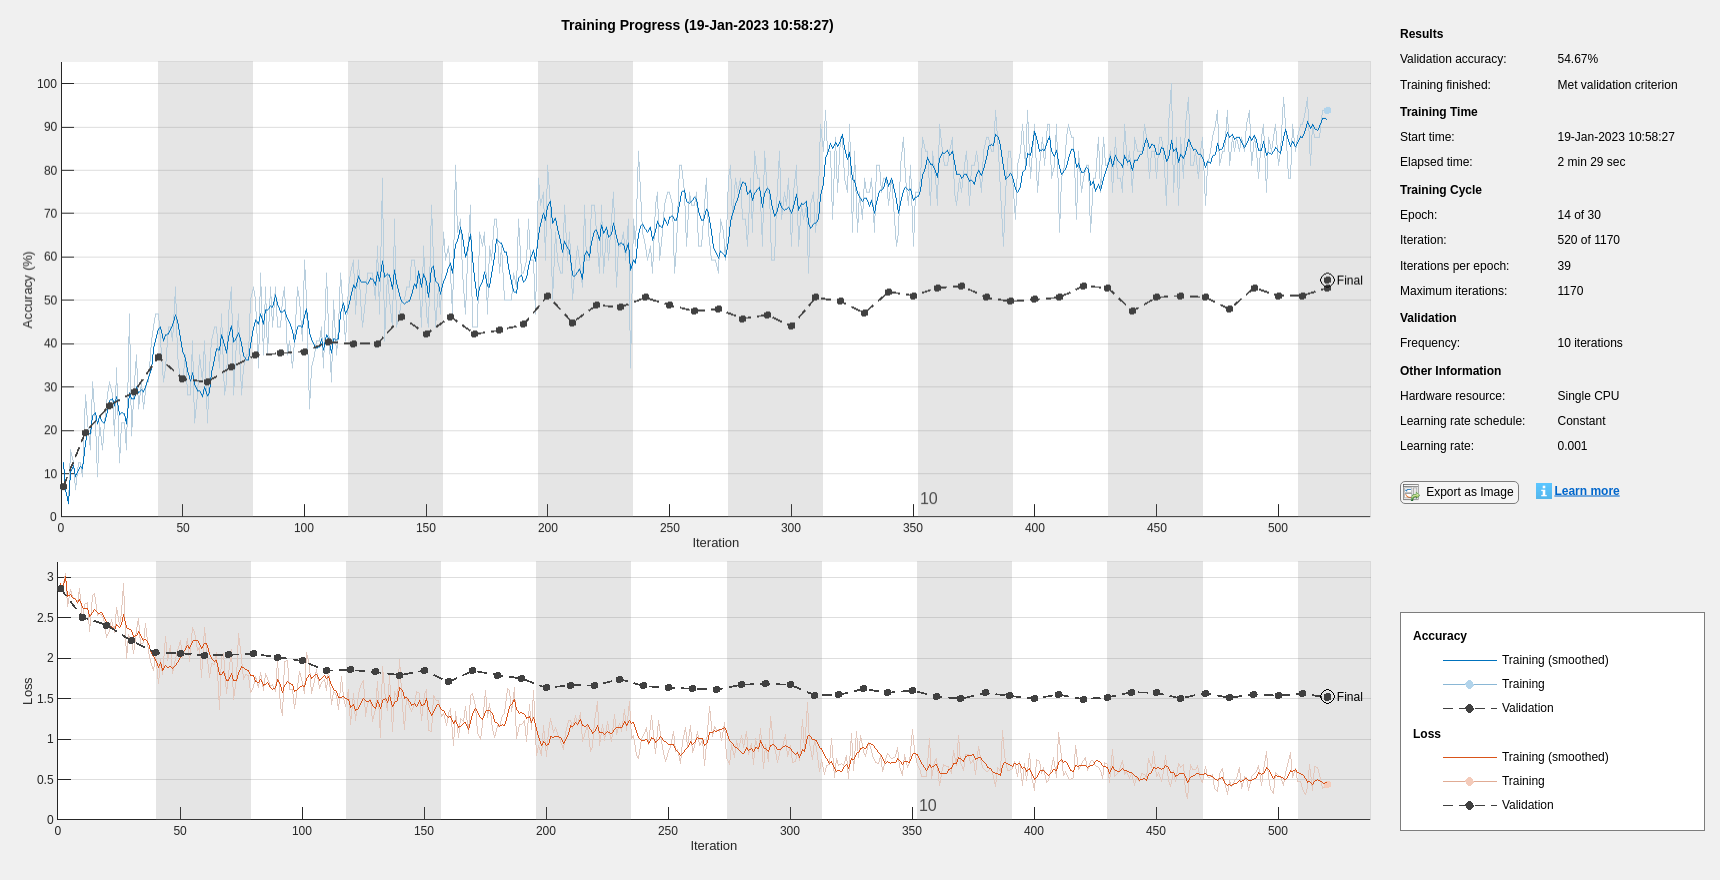

net_2 = trainNetwork(auimdsTrain,layers_2,options);

YPredicted = classify(net_2,imdsTest);

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.5474

### Change the size of the filters

layers_3 = [    
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    convolution2dLayer(3,8,'WeightsInitializer','narrow-normal', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(5,16,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(7,32,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    
    fullyConnectedLayer(15,'WeightsInitializer','narrow-normal','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

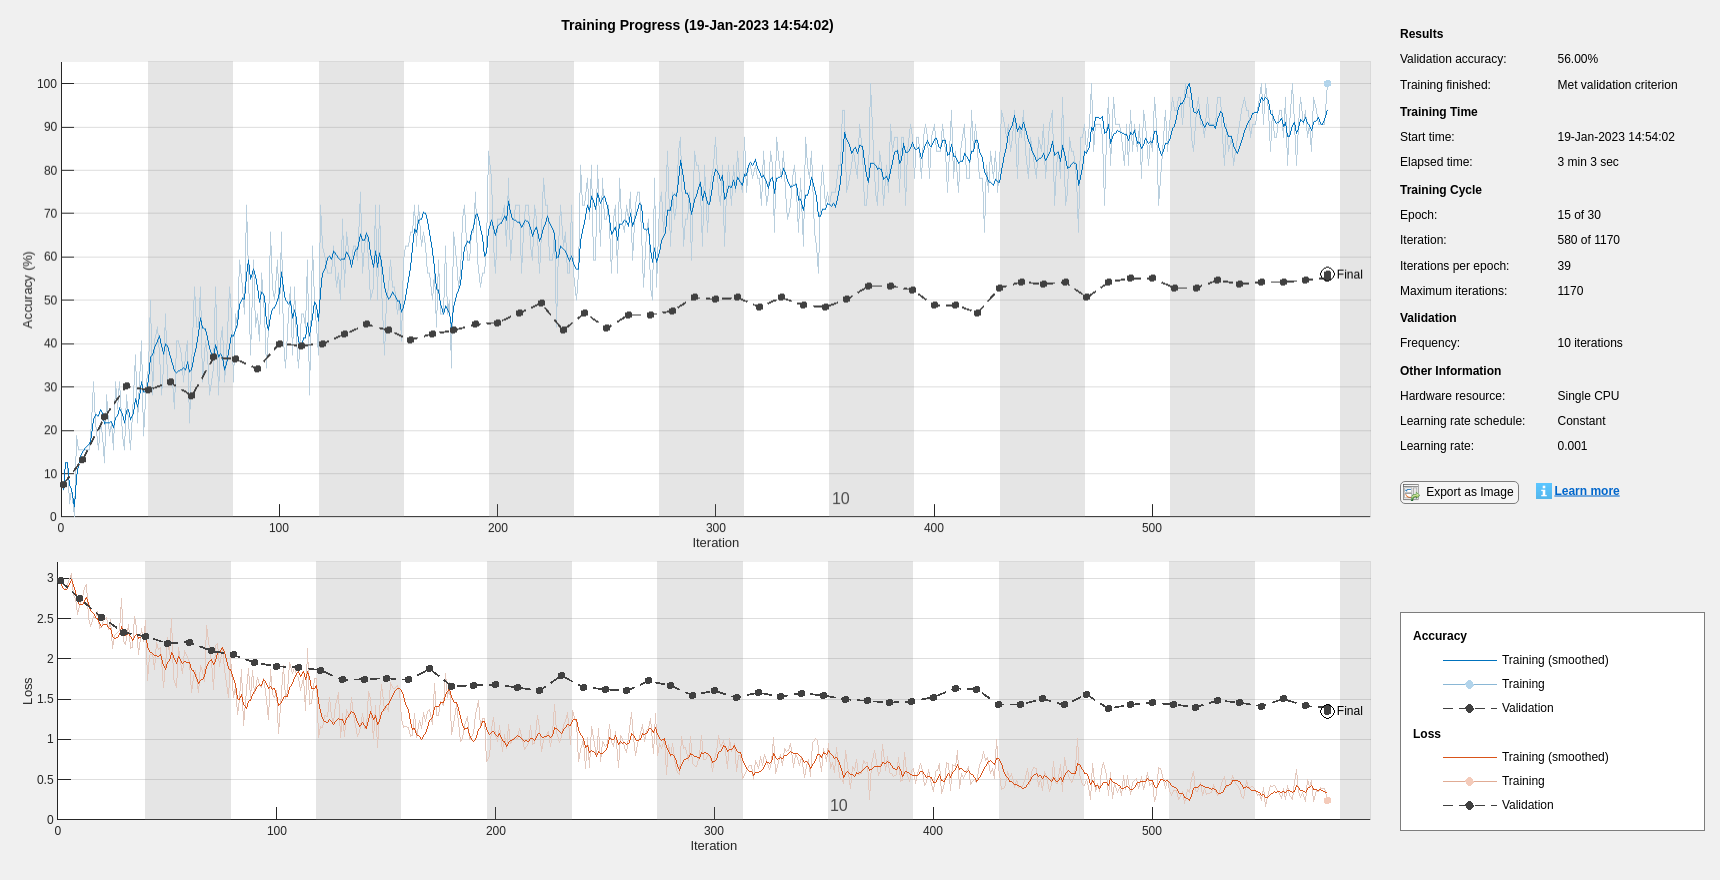

net_3 = trainNetwork(auimdsTrain,layers_3,options);

YPredicted = classify(net_3,imdsTest);

% overall accuracy Filter size
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.5742

### Play with the hyperparams - Experiment Manager

### Change optimizer to Adam

options_2 = trainingOptions('adam', ...
    'InitialLearnRate',0.001, ... 
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'ValidationPatience',10,... 
    'Verbose',false, ...
    'MiniBatchSize',32, ...
    'Plots','training-progress')

options_2 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 32
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 10
              ValidationPatience: 10
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyU

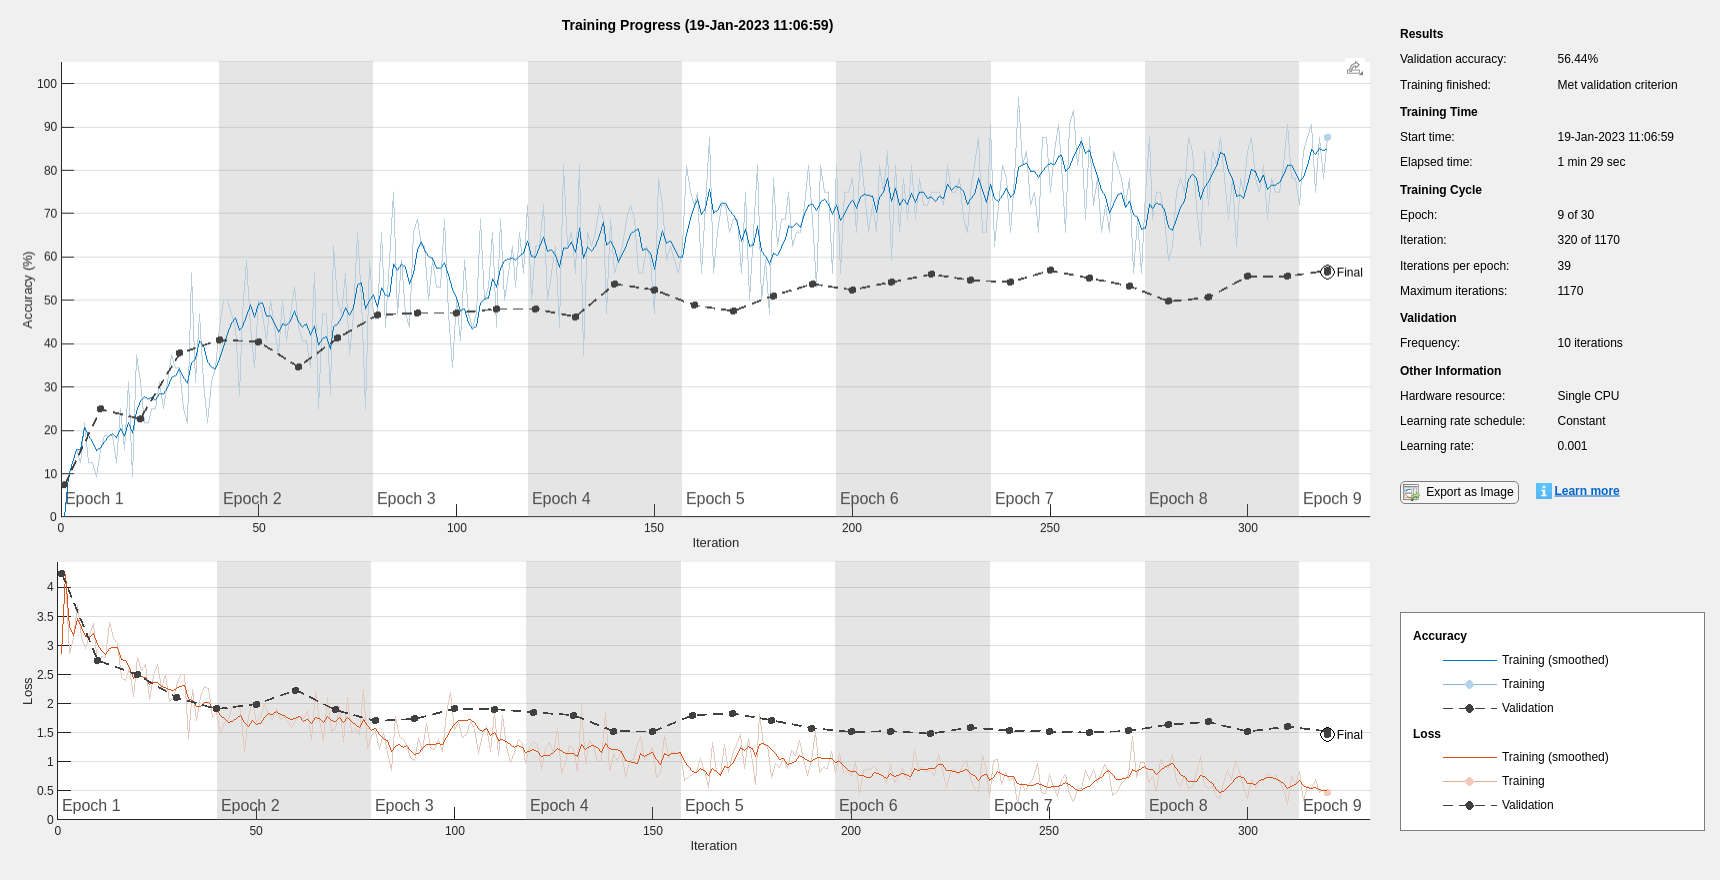

net_4 =   SeriesNetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'output'}



net_4 = trainNetwork(auimdsTrain,layers_3,options_2)

YPredicted = classify(net_4,imdsTest);

% overall accuracy Adam
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.5739

### Add dropout layer 

layers_4 = [    
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    convolution2dLayer(3,8,'WeightsInitializer','narrow-normal', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(5,16,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(7,32,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    dropoutLayer('Name','drop3')
    
    fullyConnectedLayer(15,'WeightsInitializer','narrow-normal','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

options_3 = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ... 
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'ValidationPatience',Inf,...
    'Verbose',false, ...
    'MiniBatchSize',32, ...
    'MaxEpochs', 15,...
    'Plots','training-progress')

options_3 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 32
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 10
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: [

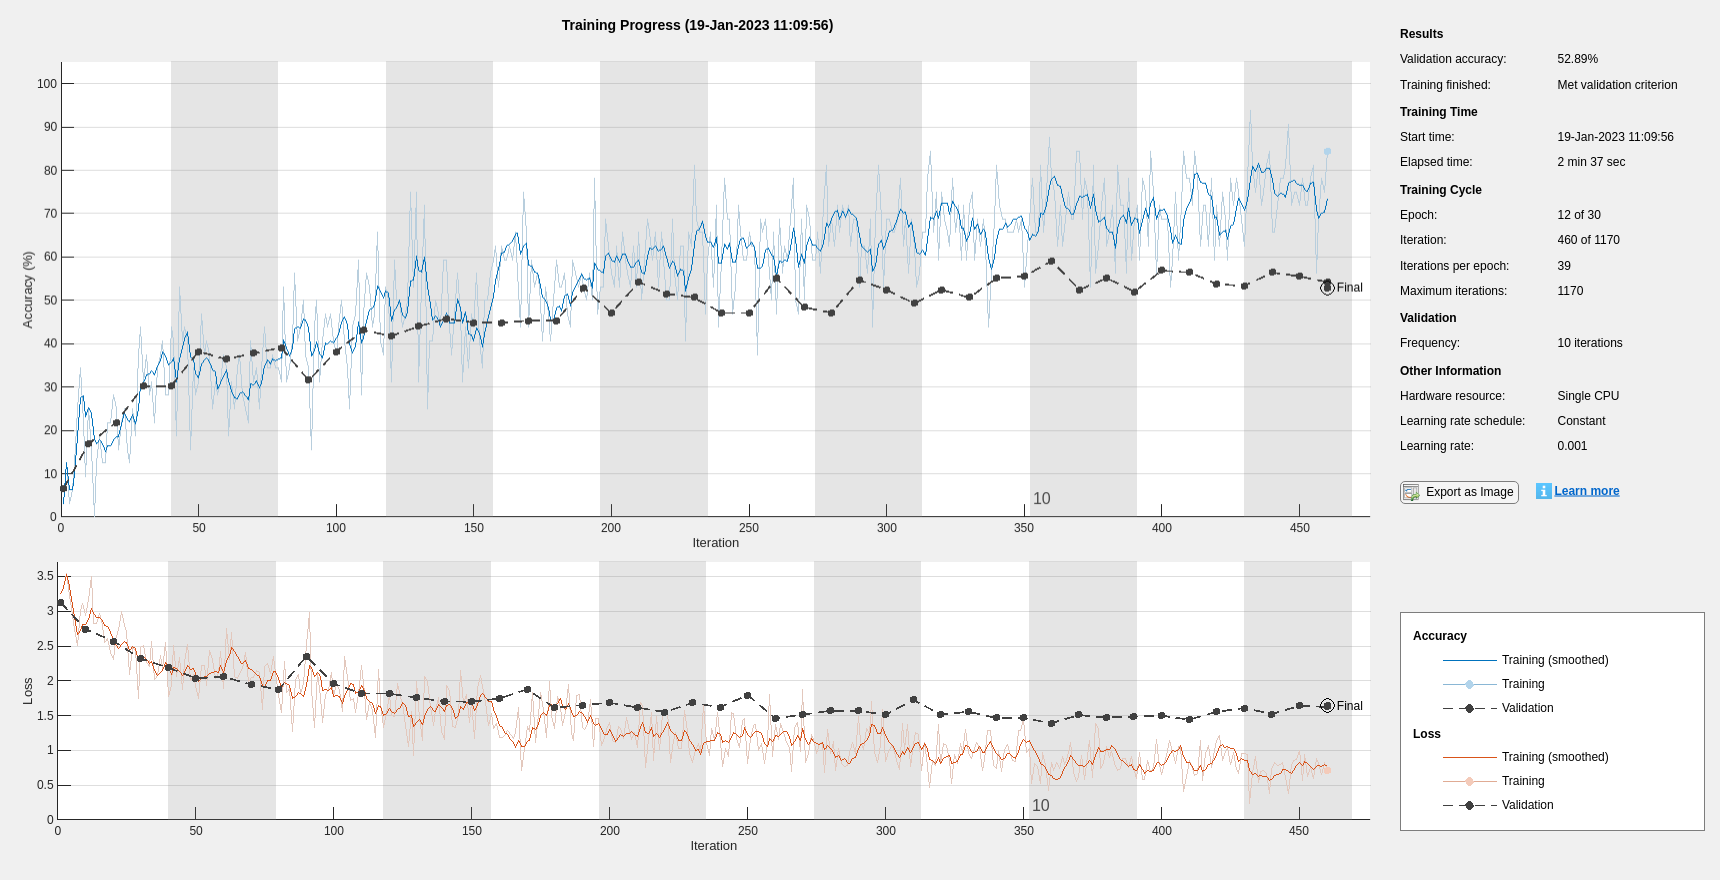

net_5 = trainNetwork(auimdsTrain,layers_4,options_2);

YPredicted = classify(net_5,imdsTest);

% overall accuracy Dropout
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.5434

### Use an ensemble tecnique

Between the previously trained networks, the architecture of the most performant one is choosen. Five networks with that architecture but different weight initializers are trained and the final prediction is the arithmetic mean of the predictions.

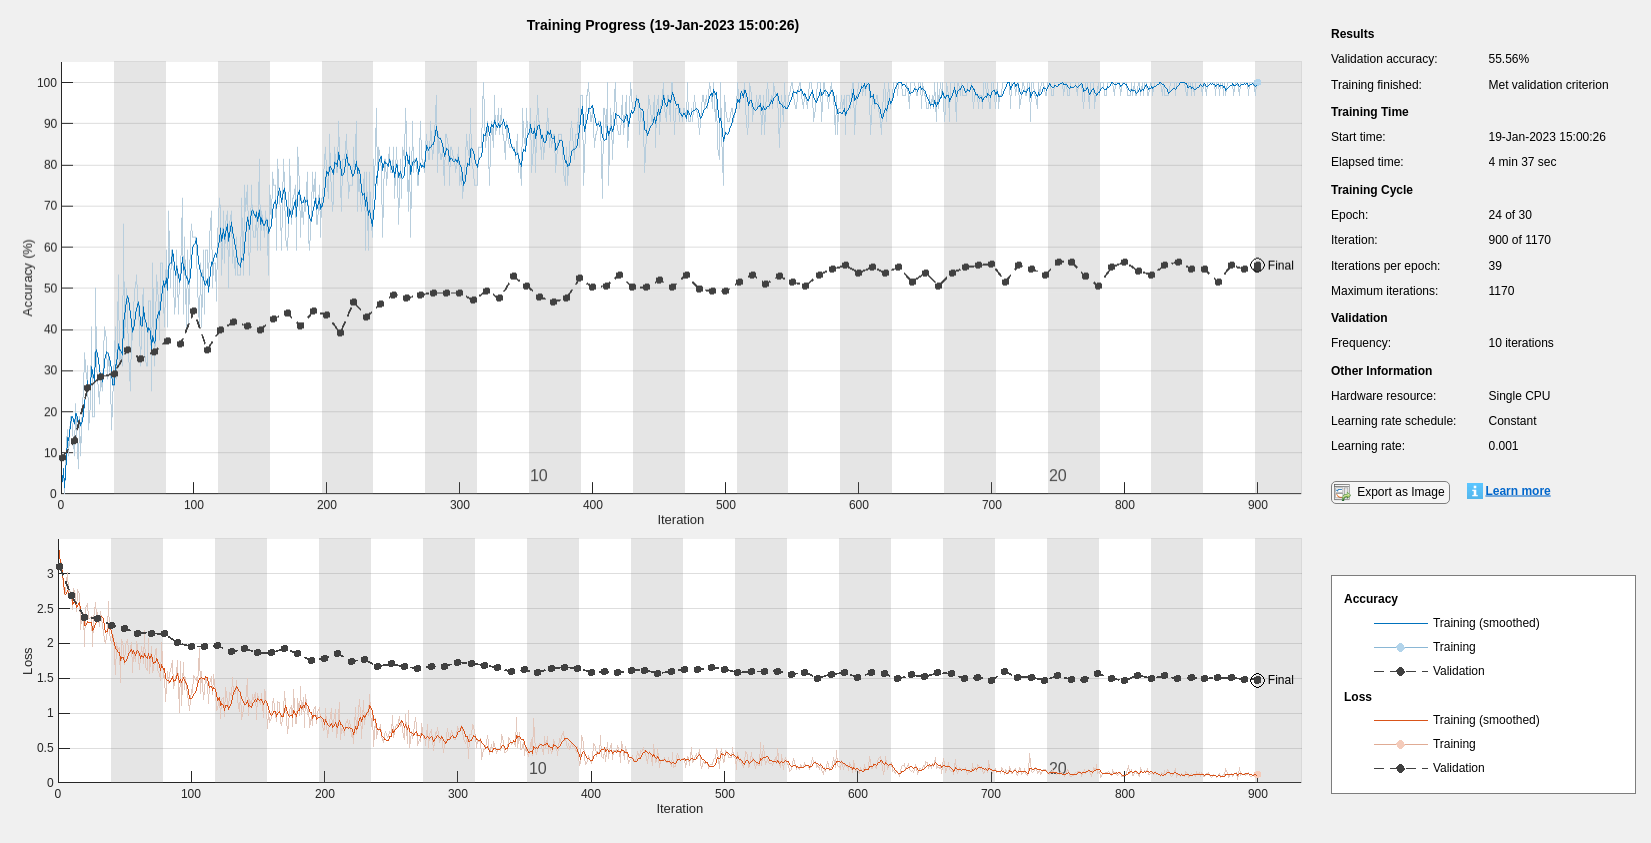

layers_5 = [    
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    convolution2dLayer(3,8,'WeightsInitializer','glorot', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(5,16,'WeightsInitializer','glorot','Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(7,32,'WeightsInitializer','glorot','Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    
    fullyConnectedLayer(15,'WeightsInitializer','glorot','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];
layers_6 = [    
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    convolution2dLayer(3,8,'WeightsInitializer','he', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(5,16,'WeightsInitializer','he','Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(7,32,'WeightsInitializer','he','Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    
    fullyConnectedLayer(15,'WeightsInitializer','he','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

net_5 = trainNetwork(auimdsTrain,layers_5,options);

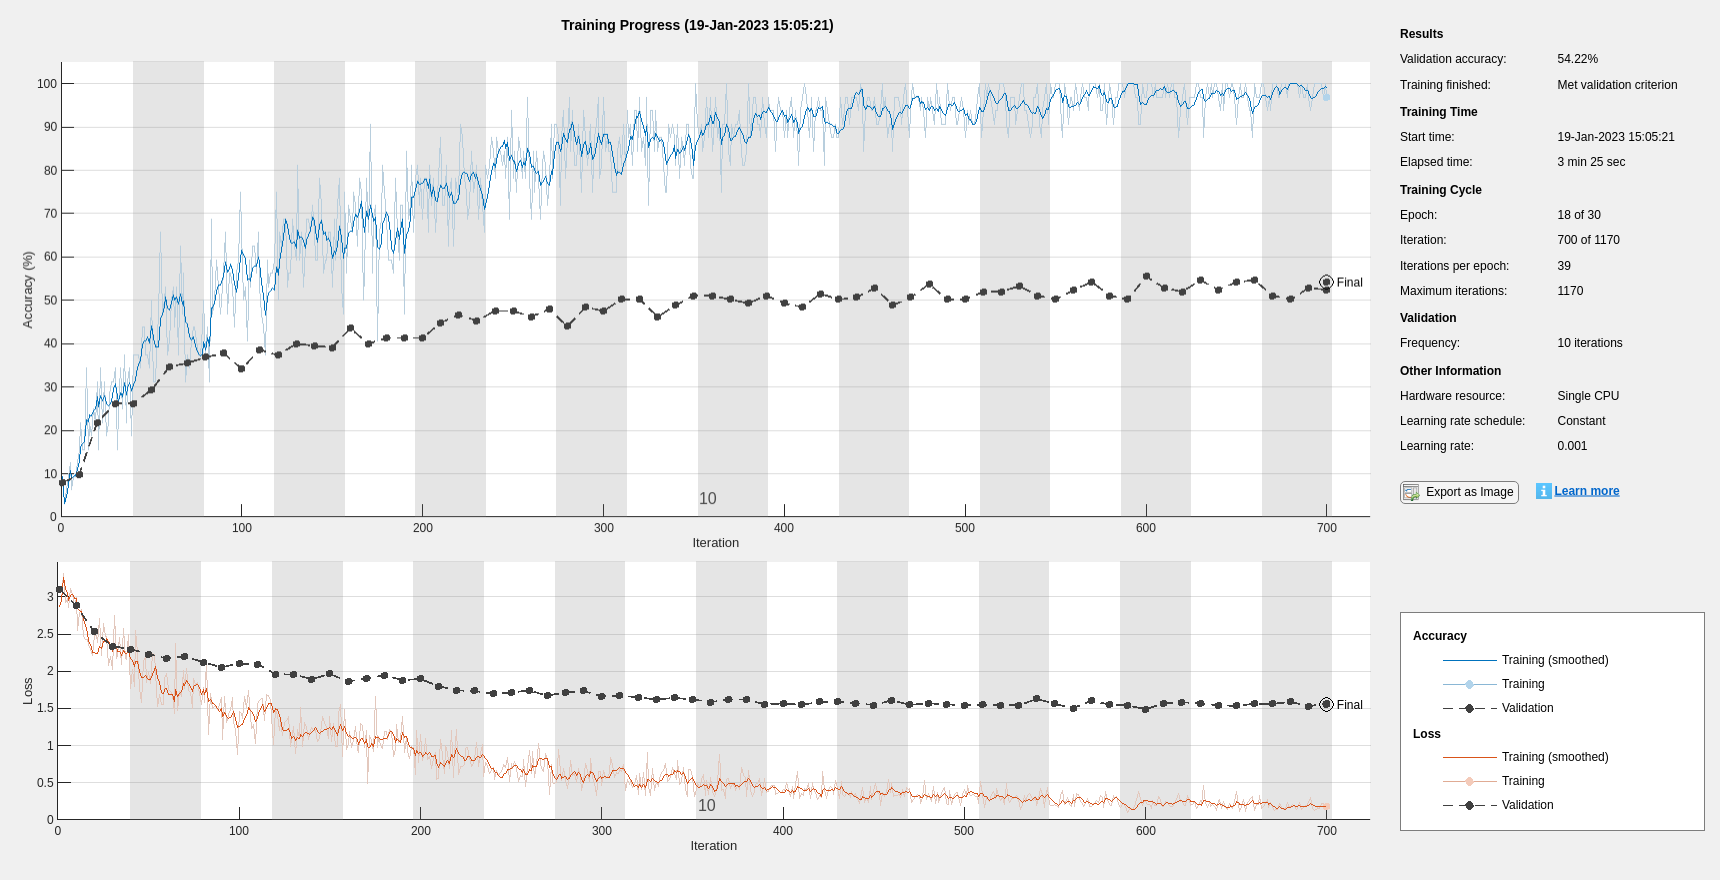

net_6 = trainNetwork(auimdsTrain,layers_6,options);

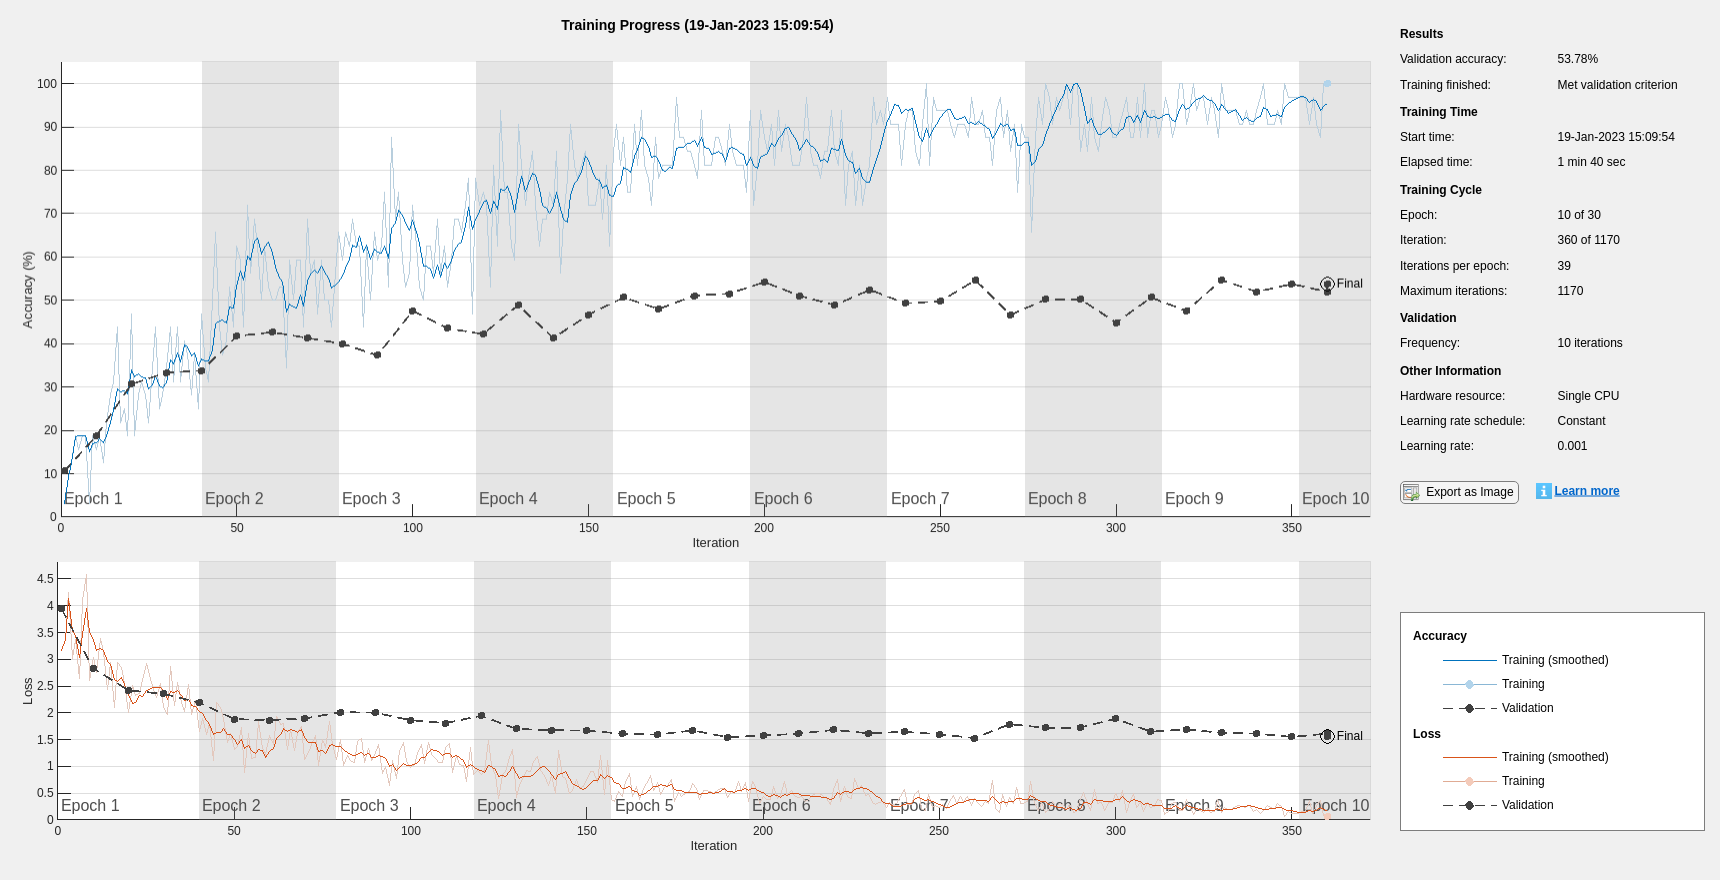

net_7 = trainNetwork(auimdsTrain,layers_5,options_2);

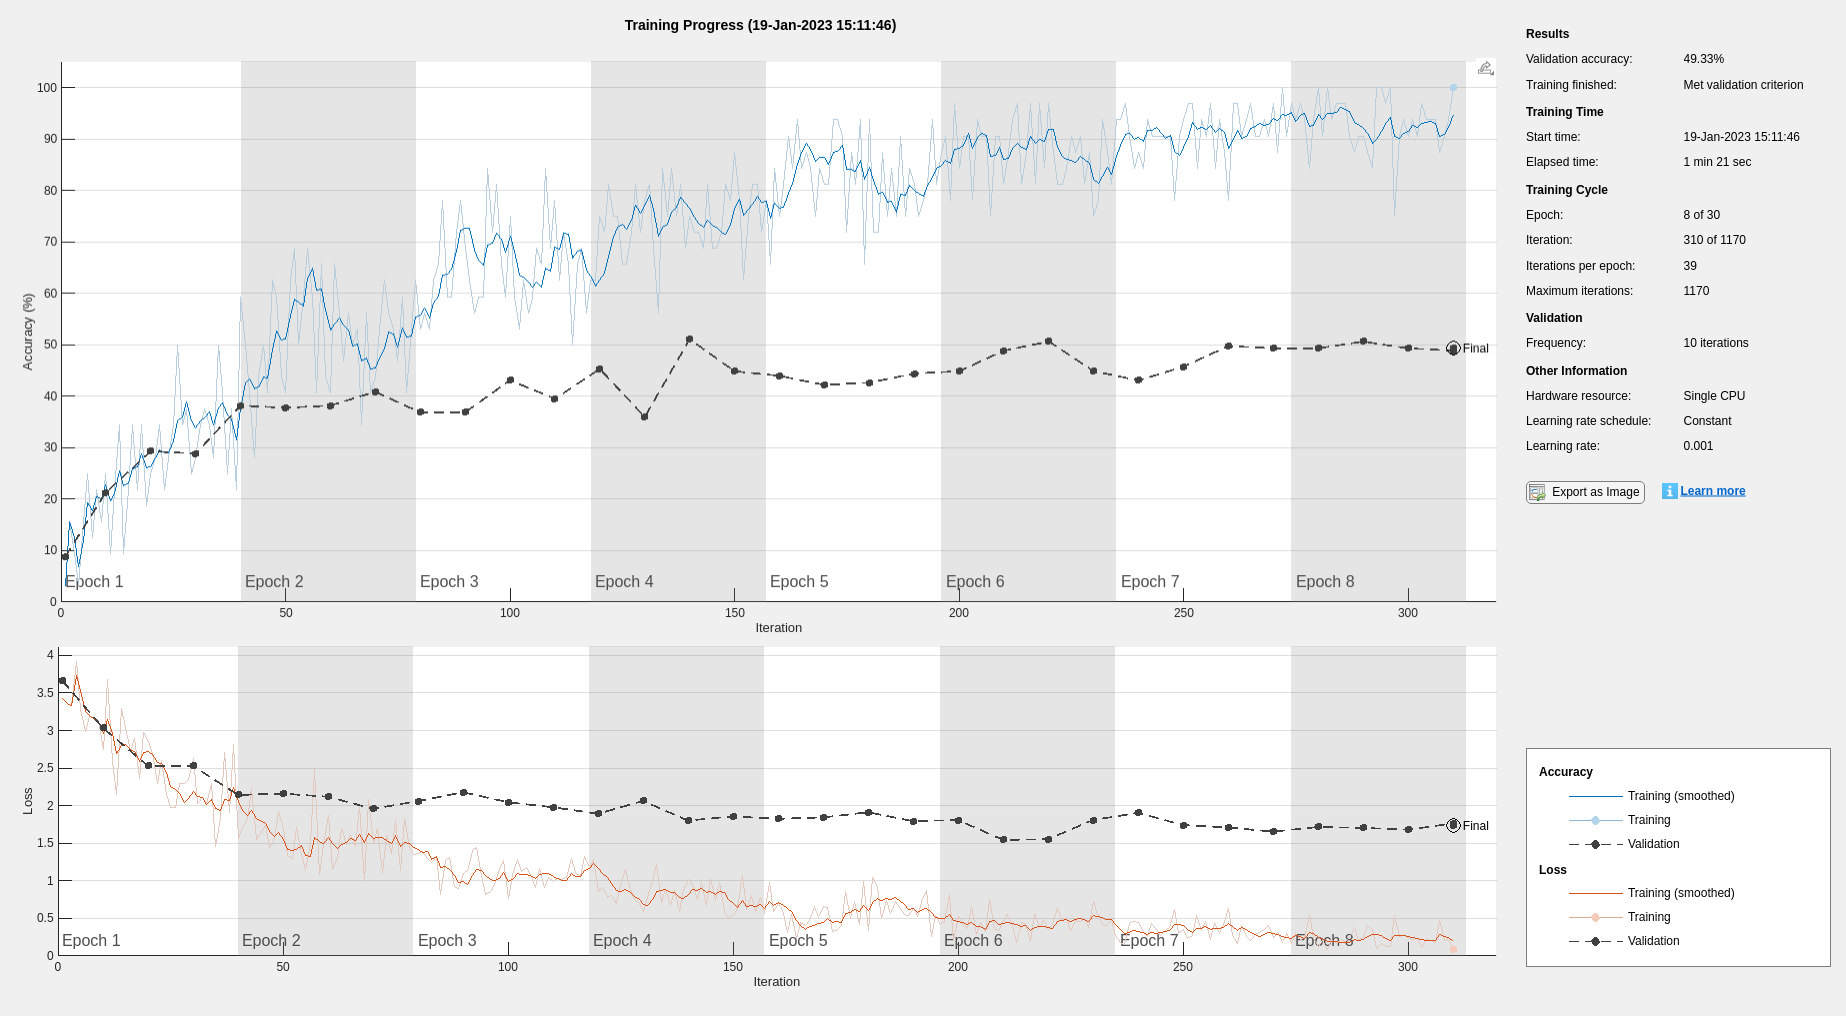

net_8 = trainNetwork(auimdsTrain,layers_6,options_2);


YPredicted0 = classify(net_3,imdsTest)

YPredicted0 = 2985×1 categorical array
     LivingRoom 
     Bedroom 
     Kitchen 
     Office 
     Kitchen 
     Office 
     Office 
     Bedroom 
     LivingRoom 
     LivingRoom 
     Kitchen 
     Office 
     LivingRoom 
     LivingRoom 
     Industrial 
     Bedroom 
     InsideCity 
     InsideCity 
     Bedroom 
     Bedroom 
     TallBuilding 
     Bedroom 
     Mountain 
     Kitchen 
     Bedroom 
     Bedroom 
     TallBuilding 
     TallBuilding 
     Bedroom 
     Suburb 


YPredicted1 = classify(net_5,imdsTest)

YPredicted1 = 2985×1 categorical array
     Industrial 
     Bedroom 
     Kitchen 
     TallBuilding 
     Kitchen 
     Bedroom 
     Office 
     Bedroom 
     LivingRoom 
     LivingRoom 
     Kitchen 
     LivingRoom 
     LivingRoom 
     LivingRoom 
     Industrial 
     Bedroom 
     InsideCity 
     InsideCity 
     Industrial 
     Bedroom 
     Bedroom 
     Bedroom 
     TallBuilding 
     Kitchen 
     Kitchen 
     TallBuilding 
     Industrial 
     TallBuilding 
     Bedroom 
     Industrial 


YPredicted2 = classify(net_6,imdsTest)

YPredicted2 = 2985×1 categorical array
     Bedroom 
     Bedroom 
     Kitchen 
     TallBuilding 
     Bedroom 
     Bedroom 
     Kitchen 
     Bedroom 
     Bedroom 
     LivingRoom 
     Kitchen 
     LivingRoom 
     LivingRoom 
     LivingRoom 
     Industrial 
     Bedroom 
     Kitchen 
     InsideCity 
     Industrial 
     Bedroom 
     Bedroom 
     Bedroom 
     InsideCity 
     Kitchen 
     Bedroom 
     Office 
     TallBuilding 
     Kitchen 
     Bedroom 
     Coast 


YPredicted3 = classify(net_7,imdsTest)

YPredicted3 = 2985×1 categorical array
     LivingRoom 
     Bedroom 
     Kitchen 
     TallBuilding 
     Kitchen 
     LivingRoom 
     Office 
     Street 
     LivingRoom 
     LivingRoom 
     LivingRoom 
     InsideCity 
     LivingRoom 
     LivingRoom 
     Industrial 
     Bedroom 
     InsideCity 
     InsideCity 
     Bedroom 
     Bedroom 
     Bedroom 
     Bedroom 
     Mountain 
     LivingRoom 
     Kitchen 
     LivingRoom 
     Store 
     Industrial 
     Bedroom 
     Bedroom 


YPredicted4 = classify(net_8,imdsTest)

YPredicted4 = 2985×1 categorical array
     LivingRoom 
     Bedroom 
     Bedroom 
     LivingRoom 
     Kitchen 
     TallBuilding 
     InsideCity 
     InsideCity 
     LivingRoom 
     LivingRoom 
     Bedroom 
     Industrial 
     LivingRoom 
     LivingRoom 
     Industrial 
     Bedroom 
     InsideCity 
     Suburb 
     LivingRoom 
     Bedroom 
     Bedroom 
     Bedroom 
     InsideCity 
     Kitchen 
     Bedroom 
     LivingRoom 
     TallBuilding 
     Kitchen 
     Bedroom 
     InsideCity 


YPredictedMatrix = [YPredicted0 YPredicted1 YPredicted2 YPredicted3 YPredicted4];
YPredicted = mode(YPredictedMatrix, 2);

% overall accuracy ensemble
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.6157

## 3. Transfer Learning

### Data preparation

% divideby=255;
% imdsTrain.ReadFcn = @(x)double(imread(x))/divideby;
% imdsValidation.ReadFcn = @(x)double(imread(x))/divideby;
% imdsTest.ReadFcn = @(x)double(imread(x))/divideby;

### Import alexnet

net = alexnet

net =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


net.Layers

ans =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0

imageSize = net.Layers(1).InputSize

imageSize =    227   227     3


### (Improved) data augmentation

augSelected = "plus pipeline" 

augSelected = "plus pipeline"



imdsTrain.ReadSize = size(imdsTrain.Files, 1);

if augSelected == 'plus pipeline'
    imdsTrain.ReadSize = size(imdsTrain.Files, 1);
    auimdsTrain = transform(imdsTrain, @dataAugmentationPipeline, 'IncludeInfo',true);    
else
    aug = imageDataAugmenter('RandXReflection',1);
    auimdsTrain = augmentedImageDatastore(imageSize,imdsTrain,'DataAugmentation',aug, 'ColorPreprocessing', 'gray2rgb');
end  

auimdsValidation = augmentedImageDatastore(imageSize,imdsValidation,'ColorPreprocessing', 'gray2rgb');
auimdsTest = augmentedImageDatastore(imageSize,imdsTest,'ColorPreprocessing', 'gray2rgb');

### 3.1. Transfer Learning Type I

Freeze the weights of all the layers but the last fully connected layer and fine-tune the weights of the last layer based on the same train and validation sets employed before;  

layersTransfer = net.Layers(1:end-3);

layers = [
    layersTransfer
    fullyConnectedLayer(15,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

options.ValidationData = auimdsValidation;

netTransfer = trainNetwork(auimdsTrain,layers,options);

[YPred,scores] = classify(netTransfer,auimdsTest);

% overall accuracy
accuracy = mean(YPred == YTest)

### 3.2. Transfer Learning Type II

Employ the pre-trained network as a feature extractor, accessing the activation of an intermediate layer (for instance the last convolutional layer) and train a multiclass linear SVM. For implementing the multiclass SVM use any of the approaches seen in the lectures, for instance DAG  

featureLayer = 'fc6'

featureLayer = 'fc6'

featuresTrain = activations(net, auimdsTrain, featureLayer, 'OutputAs', 'rows');
featuresValidation = activations(net, auimdsValidation, featureLayer, 'OutputAs', 'rows');
featuresTest = activations(net, auimdsTest, featureLayer, 'OutputAs', 'rows');

#### 3.2.1. Linear Multiclass, Nonlinear Multiclass

%selectedSVM = "nonLinSVM"

selectedSVM = "nonLinSVM"

model = ovrtrain(grp2idx(YTrain), double(featuresTrain));
[pred,ac,decv] = ovrpredict(grp2idx(YTest), double(featuresTest), model);
fprintf('Accuracy = %g%%\n', ac * 100);

Accuracy = 79.1625%


Accuracy = 45.4271%


#### 3.2.2. Multiclass SVM using Error Correcting Output Code (ECOC) 

selectedecocSVM = "ecocLinSVM" % task 6. is non linear svm

if selectedecocSVM == 'linSVM'
    t = templateLinear('Learner', 'svm', 'Regularization', 'lasso');
else
    t = templateSVM('Standardize',true,'KernelFunction','polynomial'); % 6. optionally, in task 3, you could employ nonlinear SVMs;;
end

PMdl = fitcecoc(featuresTrain,YTrain,'Learners',t,'FitPosterior',true,...
    'Verbose',2); %'OptimizeHyperparameters','auto'
Mdl = PMdl.BinaryLearners{1};           % Extract trained, compact classifier

%load('forTransferLinSVMB.mat')
YPred = predict(PMdl,featuresValidation);

table(YValidation,YPred,...
    'VariableNames',{'TrueLabels','PredictedLabels'})

idx = [1 5 10 15];
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    label = YPred(idx(i));
    
    imshow(I)
    title(label)
end

accuracy = mean(YPred == YValidation) % TODO bad accuracy (40% not >85%) needs fixing

YPred = predict(PMdl,featuresTest);

table(YTest,YPred,...
    'VariableNames',{'TrueLabels','PredictedLabels'})

idx = [1 5 10 15];
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    label = YPred(idx(i));
    
    imshow(I)
    title(label)
end

accuracy = mean(YPred == YTest)


function [dataOut,info] = dataAugmentationPipeline(dataIn,info)

dataOut = cell([size(dataIn,1),2]);

for idx = 1:size(dataIn,1)
    temp = dataIn{idx};
  
    temp = cat(3, temp, temp, temp); 
    win = randomWindow2d(size(temp), [200 200]);
    temp  = imcrop(temp, win);
    
    % Add randomized rotation and scale
    tform = randomAffine2d(Scale=[0.99 1],Rotation=[-5 5]);
    outputView = affineOutputView(size(temp),tform);
    temp = imwarp(temp,tform,OutputView=outputView);

    temp = imresize(temp,[227, 227]);

    dataOut(idx,:) = {temp,info.Label(idx)};
end

end